## 2.3 Secção para avaliação

Considere uma empresa fabricante de brinquedos que produz um determinado brinquedo. O brinquedo é composto por dois componentes (1 e 2) que são produzidos separadamente e posteriormente montados. No final, os brinquedos são embalados para comercialização em caixas com n brinquedos cada. O processo de fabrico do Componente 1 produz p1 = 0, 2% de componentes com defeito. O processo de fabrico do Componente 2 produz p2 = 0, 5% de componentes com defeito. Um brinquedo está com defeito se pelo menos um de seus componentes estiver com defeito. O processo de montagem produz pa = 1% de brinquedos com defeito (mesmo quando nenhum dos 2 componentes esta com defeito).

### 1. (Peso de avaliação = 20 %) Considere o evento ”A - uma caixa de brinquedos tem pelo menos 1 brinquedo com defeito”.

#### (a) Estime por simulação a probabilidade do evento A quando n = 8 brinquedos. 

N=1e5;                                                  % numero de experiencias
n = 8;                                                  % numero de brinquedos por caixa
experiencias = rand(n,N);                               % fabrico de peças p1
p1  = experiencias < 0.002;                             % peças p1 com defeito
experiencias = rand(n,N);                               % fabrico de peças p2
p2  = experiencias < 0.005;                             % peças p2 com defeito
experiencias = rand(n,N);                               % processo de montagem pa
pa  = experiencias < 0.01;                              % defeitos na montagem pa com defeito
ndefeitos = p1 + p2 + pa;                               % numero de defeitos por brinquedo
defeitos = ndefeitos > 0;                               % brinquedos com defeito
nbrinquedos = sum(defeitos);                            % numero de brinquedos com defeito
caixas = nbrinquedos >=1;                               % soma das caixas com pelo menos um brinquedo com defeito
probA= sum(caixas)/N                                    %calculo da probabilidade do acontecimento A

probA = 0.1263

#### (b) Estime por simulação do numero médio de brinquedos defeituosos apenas devido ao processo de montagem quando ocorre o evento A.

medias = 0;                                             % definir média para somar médias e veer valor médio das experiencias
counter = 0;                                            % definir counter para contar caixas com pelo menos 1 defeito
N=1e5;                                                  % numero de experiencias
n = 8;                                                  % numero de brinquedos por caixa
experiencias = rand(n,N);                               % fabrico de peças p1
p1  = experiencias < 0.002;                             % peças p1 com defeito
experiencias = rand(n,N);                               % fabrico de peças p2
p2  = experiencias < 0.005;                             % peças p2 com defeito
experiencias = rand(n,N);                               % processo de montagem pa
pa  = experiencias < 0.01;                              % defeitos na montagem pa com defeito
ndefeitos = p1 + p2 + pa;                               % numero de defeitos por brinquedo
defeitos = ndefeitos > 0;                               % brinquedos com defeito  
todosdef = sum(defeitos);                               % soma de todos os brinquedos defeitoosos por caixa 
mdefeitos = (p1+p2)>0;                                  % calculo de defeitos provocados por peças 
mdefeitos = (mdefeitos ~= pa) & pa;                     % calculo de defeitos provocados só por montagem
nmdefeitos = sum(mdefeitos);                            % numero de brinquedos com o defeito só de montagem
for d = 1:N                                             % for para iteração das matrizes
    if(todosdef(d) ~=0)                                 % verificação se existe pelo menos 1 brinquedo com defeito por caixa
        medias= medias + nmdefeitos(d)/todosdef(d);     % soma das médias de brinquedos defeitoosos devido a montagem em comparação aos defeitos totais por caixa
        counter = counter + 1;                          % contador de casos com pelo menos um defeito por caixa
    end                                                 % 
end                                                     %
result = medias/counter                                 % média final das médias obtidas

result = 0.5813

### 2. (Evaluation weight = 30%) Consider the event “B – a box of toys has no defective toys”.

#### (a) Estimate by simulation the probability of event B when n = 8 toys. 

N=1e5;                                                  % numero de experiencias
n = 8;                                                  % numero de brinquedos por caixa
experiencias = rand(n,N);                               % fabrico de peças p1
p1  = experiencias < 0.002;                             % peças p1 com defeito
experiencias = rand(n,N);                               % fabrico de peças p2
p2  = experiencias < 0.005;                             % peças p2 com defeito
experiencias = rand(n,N);                               % processo de montagem pa
pa  = experiencias < 0.01;                              % defeitos na montagem pa com defeito
ndefeitos = p1 + p2 + pa;                               % numero de defeitos por brinquedo
defeitos = ndefeitos > 0;                               % brinquedos com defeito
nbrinquedos = sum(defeitos);                            % numero de brinquedos com defeito
caixas = nbrinquedos ==0;                               % soma das caixas com nenhum brinquedo com nenhum defeito
probB= sum(caixas)/N                                    % calculo da probabilidade do acontecimento B

probB = 0.8724

#### Check the consistency of this result with the one obtained in question 1(a).

vrfy = probB + probA                                    % verificação se os valores da probA e probB são compativeis

vrfy = 0.9987

#### (b) Determine the theoretical value of the probability of event B and compare it with the value estimated by simulation in question 2(a). 

X = 8;                                                  % (numero de sucessos em n experiências) numero de vezes que um acontecimento A ocorre em
n = 8;                                                  % n experiências de Bernoulli
k = X;                                                  % Pr(X=k)
p1 = 0.002;                                             % probabilidade das peças p1 terem defeito
p2 = 0.005;                                             % probabilidade das peças p2 terem defeito
pa = 0.01;                                              % probabilidade da montagem ter defeito
p = ((1-p1)*(1-p2)*(1-pa));                             % probabilidade do brinquedo não ter defeito, devido a ser sem defeito quer-se-á a probabilidade ~p1 e ~p2 e ~pa, sendo estes acontecimentos independentes tem-se então k a probabilidade destes acontecimentos acontecerem é igual à multiplicação destes 
probtheo = nchoosek(n,k)*p^k*(1-p)^(n-k)                % probabilidade teórica = nchoosek(n,k)*p^k*(1-p)^(n-k) em que nchoosek(n,k)= n!/(n-k)!/k!

probtheo = 0.8724

#### What do you conclude?

probB   

probB = 0.8724

probtheo

probtheo = 0.8724

Pode-se concluir assim que as probabilidades obtidas por simulação e teoricamente são bastante próximas

#### (c) Make the necessary simulations to draw a plot graph of the probability of event B as a function of the box capacity n. Consider all values of n from 2 to 20. 

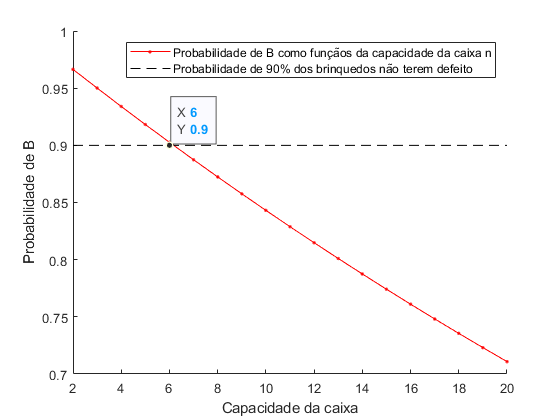

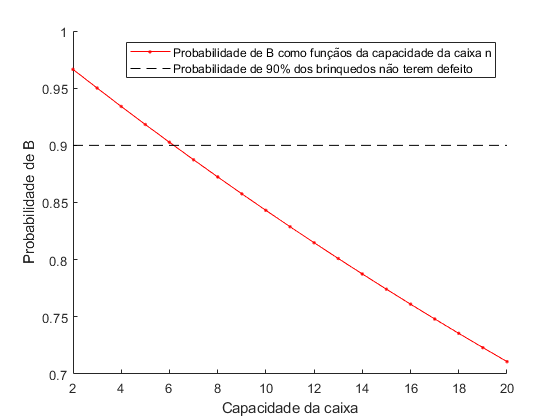

y = (2:20);                                                 % probabilidade do acontecimento B em função da capacidade da caixa
for k =  2:20                                               % (numero de sucessos em n experiências) numero de vezes que um acontecimento A ocorre em n experiências de Bernoulli de 2 a 20
    n =  k;                                                 % n experiências de Bernoulli
    p1 = 0.002;                                             % probabilidade das peças p1 terem defeito
    p2 = 0.005;                                             % probabilidade das peças p2 terem defeito
    pa = 0.01;                                              % probabilidade da montagem ter defeito
    p = ((1-p1)*(1-p2)*(1-pa));                             % probabilidade do brinquedo não ter defeito, devido a ser sem defeito quer-se-á a probabilidade ~p1 e ~p2 e ~pa, sendo estes acontecimentos independentes tem-se então k a probabilidade destes acontecimentos acontecerem é igual à multiplicação destes 
    y(k-1) = nchoosek(n,k)*p^k*(1-p)^(n-k);                 % y = probabilidade teórica = nchoosek(n,k)*p^k*(1-p)^(n-k) em que nchoosek(n,k)= n!/(n-k)!/k!
end
hold on;
plot(2:20,y,"r.-");
plot(2:20,ones(19)*0.9,"k--");
xlabel ("Capacidade da caixa");
ylabel ("Probabilidade de B");
legend ("Probabilidade de B como funçãos da capacidade da caixa n","Probabilidade de 90% dos brinquedos não terem defeito");
hold off;

#### Describe and justify the obtained results.

#### (d) Analysing the plot drawn in the previous question 2(c), what must be the maximum box capacity if the company wants to guarantee that the probability of each box having no defective toys is at least 90%? 

Em (6,0.9);